**Vehicle Segmentation and Motion Direction Estimation using Optical Flow**

**Project Introduction**

This project demonstrates a powerful computer vision technique for analyzing traffic flow by detecting moving vehicles and estimating their direction of travel using **Optical Flow**. By analyzing the motion vectors between two consecutive video frames, this system can differentiate moving cars from the static background, segment them, and quantify traffic patterns.

The primary objectives are to:

- **Generate a motion mask** that isolates fast-moving objects (vehicles) from the scene.

- **Use optical flow vectors** to compute the direction and count of cars moving left and right.

This project showcases an end-to-end pipeline, from initial image loading to final motion analysis, providing a foundation for more advanced applications in intelligent traffic monitoring, vehicle tracking, and real-time transportation analytics.

**Step 1: Load Image Frames**

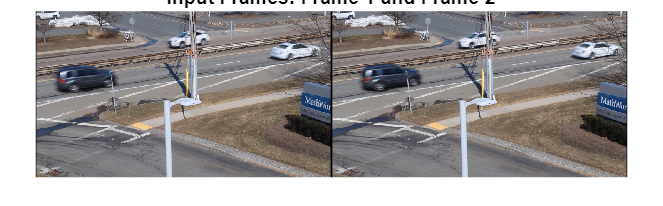

frame1 = imread("Rt9Frame1.png");
frame2 = imread("Rt9Frame2.png");

% Visualize frames side by side
figure; montage({frame1, frame2}); title("Input Frames: Frame 1 and Frame 2")

**Step 2: Initialize Optical Flow and Estimate Flow**

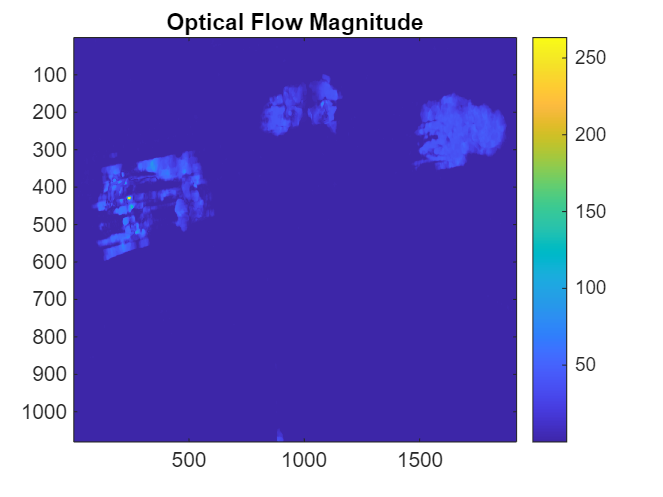

% Initialize Farneback optical flow object
myOpticalFlowCars = opticalFlowFarneback;

% Estimate optical flow from frame1 to frame2
estimateFlow(myOpticalFlowCars, im2gray(frame1)); % Initialize with first frame
flow = estimateFlow(myOpticalFlowCars, im2gray(frame2));

% Visualize optical flow magnitude
figure; imagesc(flow.Magnitude); colorbar; title("Optical Flow Magnitude")

**Step 3: Create Mask of Fast-Moving Regions (Cars)**

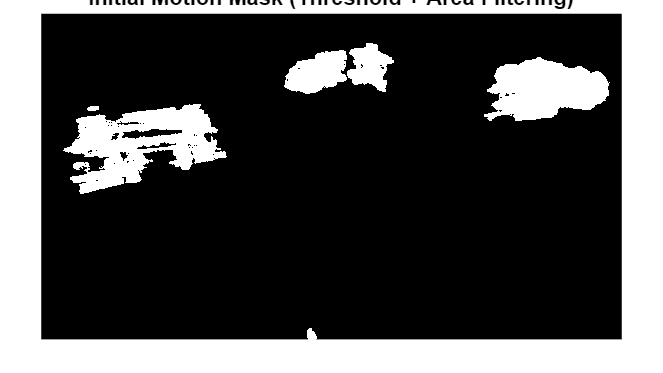

% Threshold on flow magnitude to capture significant movement (cars)
magTH = 1;
mask = (flow.Magnitude > magTH);

% Remove small regions (noise), keep regions with at least 500 pixels
mask = bwareafilt(mask, [500, inf]);
imshow(mask, []); title("Initial Motion Mask (Threshold + Area Filtering)")

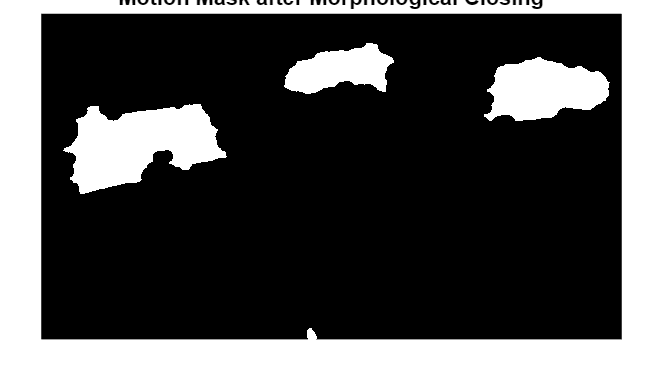


% Morphological closing to fill gaps and smooth the mask
se = strel("disk", 20, 0);
mask = imclose(mask, se);
imshow(mask, []); title("Motion Mask after Morphological Closing")


% Remove small regions (noise), keep regions with at least 1000 pixels
mask = bwareafilt(mask, [1000, inf]);

**Step 4: Apply Mask and Visualize Detected Moving Cars**

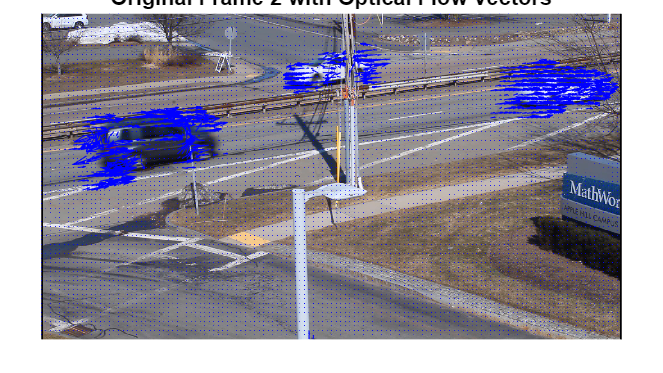

% Mask the original image to isolate detected moving vehicles
maskedFrame = frame2;
maskedFrame(repmat(~mask, [1, 1, 3])) = 0;

% Show original frame with optical flow vectors overlaid
imshow(frame2); title("Original Frame 2 with Optical Flow Vectors")
hold on;
plot(flow, "DecimationFactor", [15 15], "ScaleFactor", 7);
hold off;

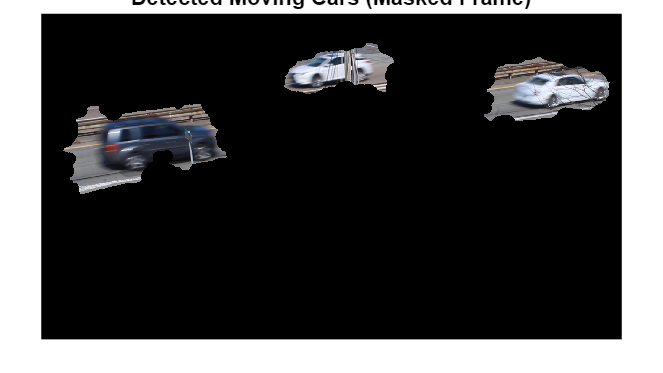


% Show masked result: detected moving cars only
imshow(maskedFrame); title("Detected Moving Cars (Masked Frame)")

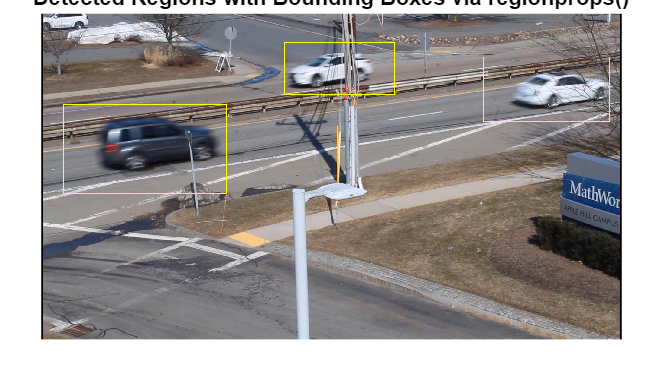


% Get region properties, including bounding boxes
props = regionprops(mask, 'BoundingBox');
bboxes = vertcat(props.BoundingBox);
imgOverlay = insertShape(frame2, "Rectangle", bboxes, "Color", "yellow", "LineWidth", 3);
imshow(imgOverlay);
title("Detected Regions with Bounding Boxes via regionprops()");

**Step 5: Analyze Velocity to Determine Traffic Direction**

% Measure mean optical flow (x-direction) for each detected moving region
Vx = regionprops("table", mask, flow.Vx, "MeanIntensity");

% Define velocity threshold to determine direction
vTH = 3;

% Separate moving regions by direction
leftVx = Vx.MeanIntensity(Vx.MeanIntensity < -vTH);
rightVx = Vx.MeanIntensity(Vx.MeanIntensity > vTH);

% Count number of detected cars moving left and right
numCarsLeft = height(leftVx);
numCarsRight = height(rightVx);

% Display results
fprintf("Number of cars moving LEFT: %d\n", numCarsLeft);

Number of cars moving LEFT: 1


fprintf("Number of cars moving RIGHT: %d\n", numCarsRight);

Number of cars moving RIGHT: 2


*Author: Kirubhakaran Meenakshi Sundaram*

*LinkedIn: https://www.linkedin.com/in/kirubhakaranm/*